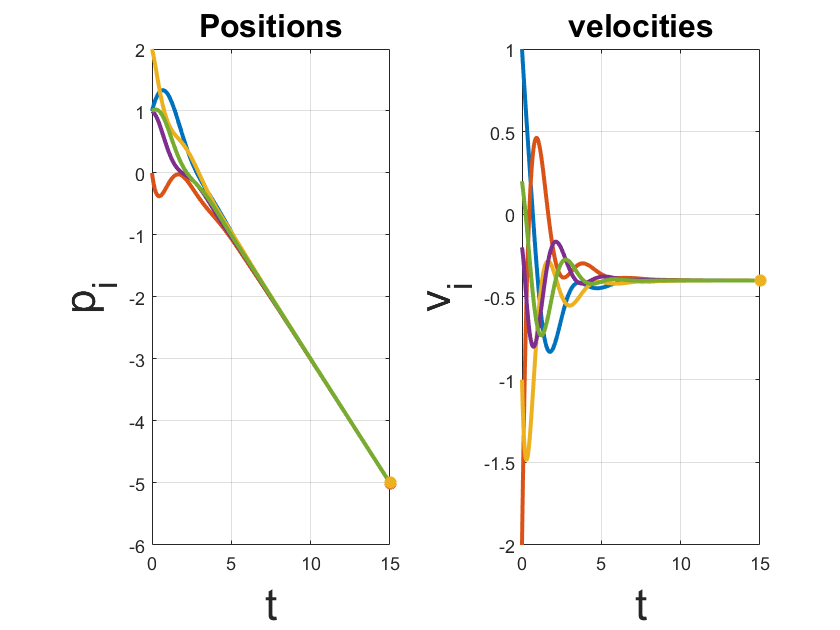

clear all;
close all;
clc;
% _________________problem 5.1_________________
tspan = [0 15];

%graph a
% L=[0 0 0 0 0;
%     -1 1 0 0 0;
%     0 -1 1 0 0;
%     0 0 -1 1 0;
%     0 0 0 -1 1];
%graph b
L=[1 0 0 0 -1;
    -1 1 0 0 0;
    0 -1 1 0 0;
    0 0 -1 1 0;
    0 0 0 -1 1];
gamma=2;

a = [zeros(5,5),eye(5);
        -L,-gamma*L];
%b=zeros(10,1)
x0 = [1;0;2;1;1; 1; -2;-1;-0.2; 0.2];
options = odeset('RelTol',1e-5);
[t, x] = ode45(@(t,x) odefun(t,x,a), tspan, x0, options);

figure(1)
subplot(1,2,1)

plot(t,x(:,1:5),'linewidth',2)
hold on
plot(t(end,:),x(end,1:5),'*','linewidth',2);
xlabel('t', 'FontSize', 22);
ylabel('p_i', 'FontSize', 22);
title('Positions', 'FontSize', 16)
%legend('1','2','3','4', '5','final pos of 1','final pos of 2','final pos of 3','final pos of 4','final pos of 5','FontSize', 22)
grid on

subplot(1,2,2)

plot(t,x(:,6:10),'linewidth',2)
hold on
plot(t(end,:),x(end,6:10),'*','linewidth',2);
xlabel('t', 'FontSize', 22);
ylabel('v_i', 'FontSize', 22);
title('velocities', 'FontSize', 16)
%legend('1','2','3','4', '5','final vel of 1','final vel of 2','final vel of 3','final vel of 4','final vel of 5','FontSize', 22)
grid on

%_________________function definition__________________

function dxdt = odefun(t, x, a)
    dxdt = a*x ;
end
